# Okumura-Hata and Cost-Hata Models

## Calculates distance based on Hata models.

- Only Okumura-Hata and Cost-Hata Models.

- Okumura-Hata Frequency Range : 100 to 1500 MHz.

- Cost-Hata Frequency Range : 1500 to 2000 MHz.

### Inputs:

- Model ["Okumura","Cost"].

- Environment ["Urban Large Cities","Urban Small Cities","Suburban Large Cities","Suburban Small Cities"].

- Path Loss (dB).

- Frequency (MHz).

- Transmitter Height (m).

- Receiver Height (m).

### Output:

- Distance (m).

function d = Hata(Model,Environment,PL,f,h_TX,h_RX)
    switch (Model)
        case "Okumura"
            A1=69.55;
            A2=26.16;
            A3=-13.82;
            B1=44.9;
            B2=-6.55;
        case "Cost"
            A1=49.3;
            A2=33.9;
            A3=-13.82;
            B1=44.9;
            B2=-6.55;
    end
    switch (Environment)
        case "Urban Large Cities"
            a=3.2*(log10(11.75*h_RX))^2-4.97;
        case "Urban Small Cities"
            a=(1.1*log10(f)-0.7)*h_RX-(1.56*log10(f)-0.8);
        case "Suburban Large Cities"
            a=3.2*(log10(11.75*h_RX))^2-4.97-2*(log10(f/28))^2;
        case "Suburban Small Cities"
            a=(1.1*log10(f)-0.7)*h_RX-(1.56*log10(f)-0.8)-2*(log10(f/28))^2;
    end
    d=10^((PL-A1-A2*log10(f)-A3*log10(h_TX)-a)/(B1+B2*log10(h_TX)));
end

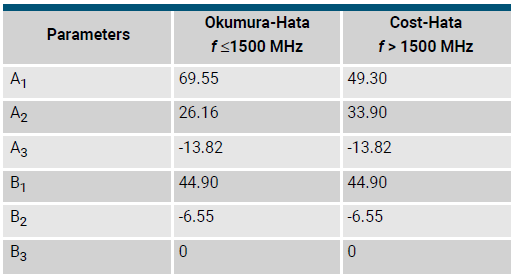

## **References:**

- **Atoll User Manual Radio.**

- **Atoll Technical Reference Guide Radio.**